# Change Data Normalization in Plot

Create a parallel coordinates plot from a table of power outage data. Change the normalization method for the numeric coordinate variables.

Read the power outage data into the workspace as a table. Display the first few rows of the table.

outages = readtable('outages.csv');
head(outages)

Create a new variable called `OutageDuration` that indicates how long each power outage lasted. Convert `OutageDuration` to the number of days each power outage lasted. Add the new variable to the `outages` table, and call it `OutageDays`.

OutageDuration = outages.RestorationTime - outages.OutageTime;
outages.OutageDays = days(OutageDuration);

Create a parallel coordinates plot using the `Loss`, `Customers`, and `OutageDays` variables. Because the coordinate variables are numeric, display the values in the plot as z-scores, without any jittering, using the `'DataNormalization'` and `'Jitter'` name-value pair arguments.

coordvars = {'Loss','Customers','OutageDays'};
p = parallelplot(outages,'CoordinateVariables',coordvars,'DataNormalization','zscore','Jitter',0);

The `OutageDays` variable contains one value that is more than 30 standard deviations away from the mean `OutageDays` value and another value that is more than 10 standard deviations away from the mean. Hover over the values in the plot to display data tips. Each data tip indicates the row in the table corresponding to the line in the plot.

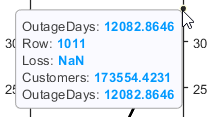

Find the rows in the `outages` table that have the identified extreme `OutageDays` values. Notice that the `RestorationTime` values for these two power outages are suspicious.

outliers = outages([1011 269],:)

*Copyright 2018 The MathWorks, Inc.*